## Step 0 | Identify videos

% Use this to identify dimensions: 
% Example
% >>PlaySeqFile('24-13')
% 20210824-20-24-13.000.seq
% 't range is [330.00 330.10] (seconds)'
%  'Size of this video 20210824-20-24-13.000.seq is 
%       [ 900 1104]' % (This is the side video)
% >>PlaySeqFile('24-16')
% 20210824-20-24-16.000.seq
%   't range is [330.00 330.10] (seconds)'
%     'Size of this video 20210824-20-24-16.000.seq is 
%       [ 550  752]'
[file_names, names] = Spikes.Videos.getVideoInfos([900 1104], [550 752]);
disp(file_names)
disp(names')

## Step 1 | Extract frame times and ROI amplitude (for alignment)

%%
% Get frame information and ROI time [384.00 384.10] 
t_sec               =       373;
framerate           =       10;
t_check             =       [0 5]+(t_sec)*100;
tic
% >>x=dir('*.seq')'
% >>arrayfun(@(x)x.name, x, 'UniformOutput', false)'
% ans =
%   4×1 cell array
%     {'20210823-16-00-02.000.seq'}
%     {'20210823-16-00-04.000.seq'}
%     {'20210823-16-20-31.000.seq'}
%     {'20210823-16-20-34.000.seq'}

for i =1:length(names)
    if any(ismember(names{i}, 'SideView')) % side view
        GetSeqFrameInfo(file_names(i), t_check, names{i}, 1);
    elseif  any(ismember(names{i}, 'TopView'))% top view
        GetSeqFrameInfo(file_names(i), t_check, names{i}, 0);
    end
end

ans = 'Extracting ......'

toc

## Step 2 | Align frames to behavior

### Gather trigger time from r

Look for r file

r_file = dir('RTarray*.mat')
if ~isempty(r_file) && length(r_file)== 1
    load(r_file.name)
end
TriggerTime = Spikes.Videos.ExtractTrigger(r);% trigger time in seconds

### Gather LED onset time, and align it to Ephys' time

Select mulitple points to define a decision boundary, end selection by right click


#############################
########## Please wait #########
#############################
Elapsed time is 0.252085 seconds.


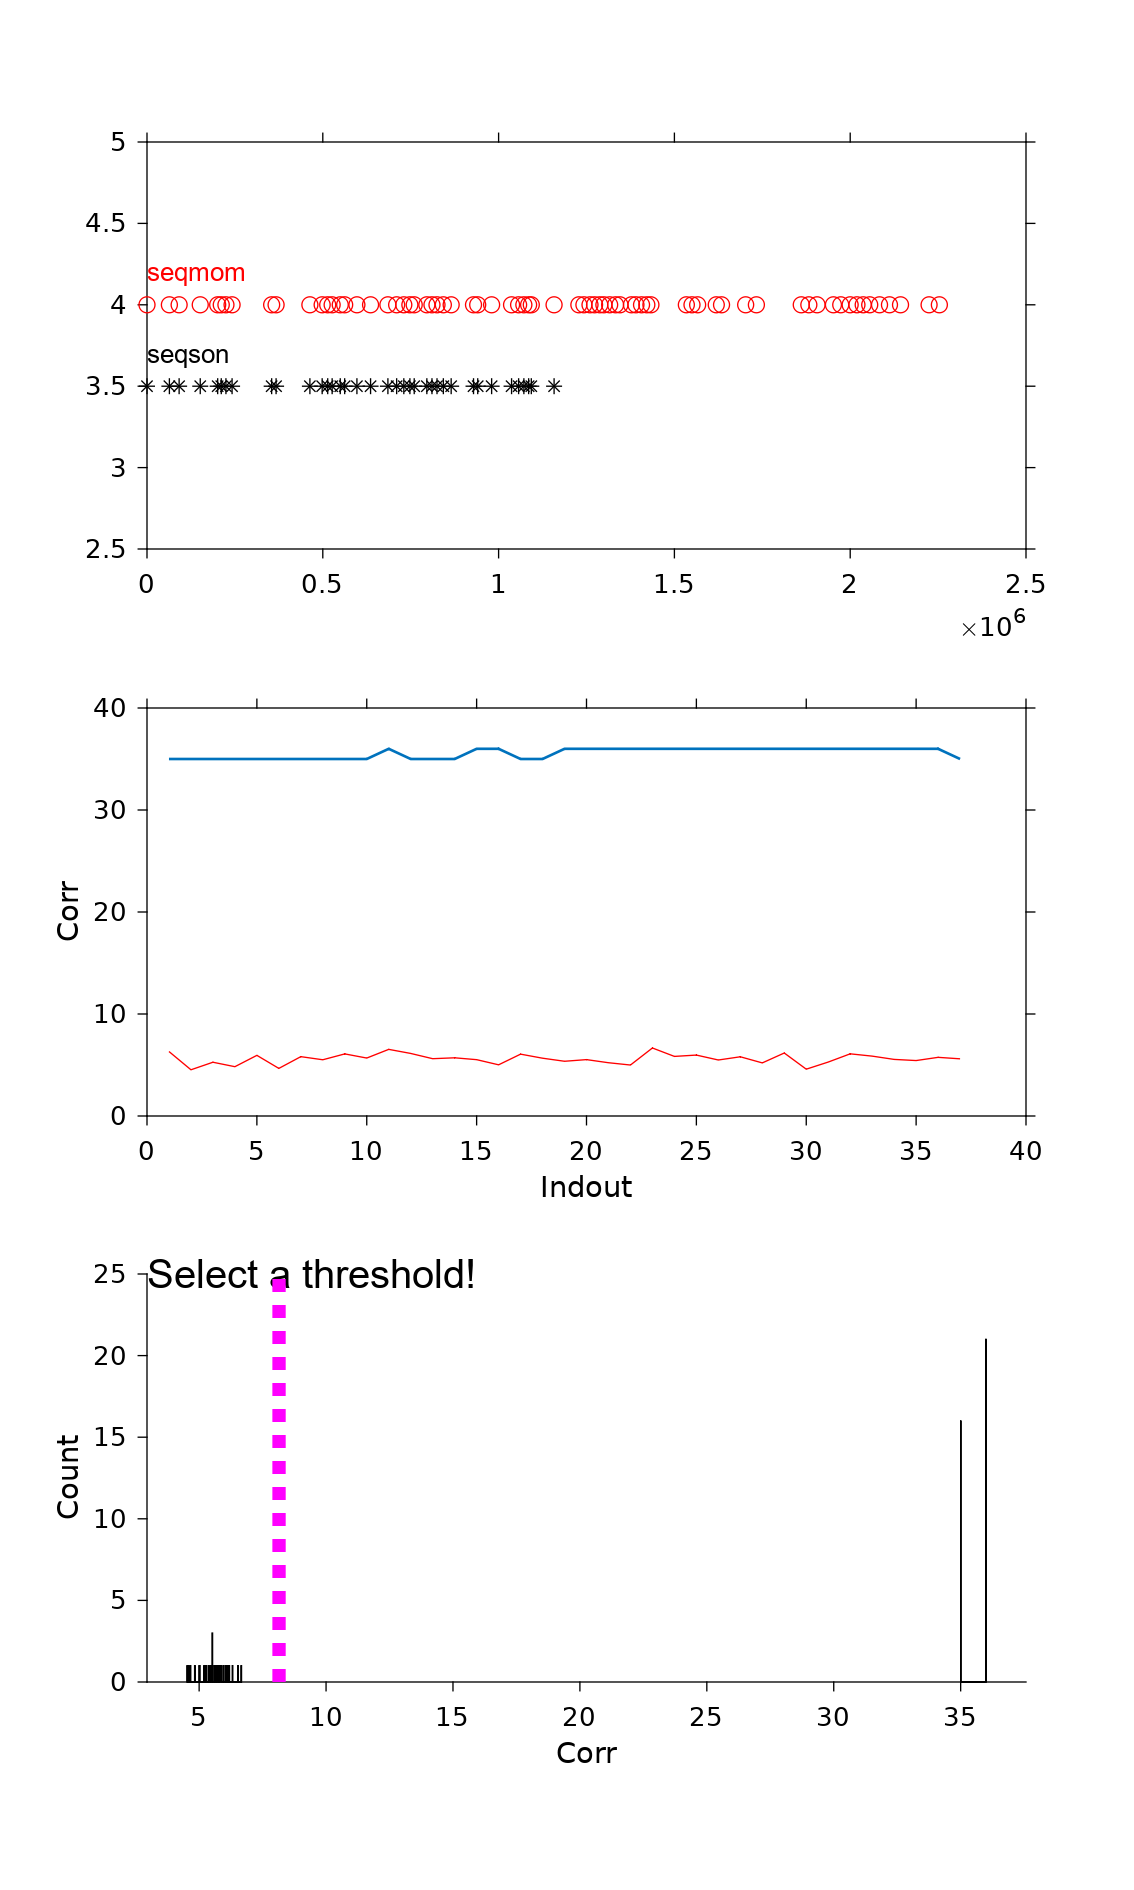

Define the threshold
Threshold defined
Define the threshold
Threshold defined
#############################
######### Done correcting #######
#############################


#############################
########## Please wait #########
#############################
Elapsed time is 0.206085 seconds.


Select mulitple points to define a decision boundary, end selection by right click


#############################
########## Please wait #########
#############################
Elapsed time is 0.180614 seconds.


Define the threshold
Threshold defined
Define the threshold
Threshold defined
#############################
######### Done correcting #######
#############################


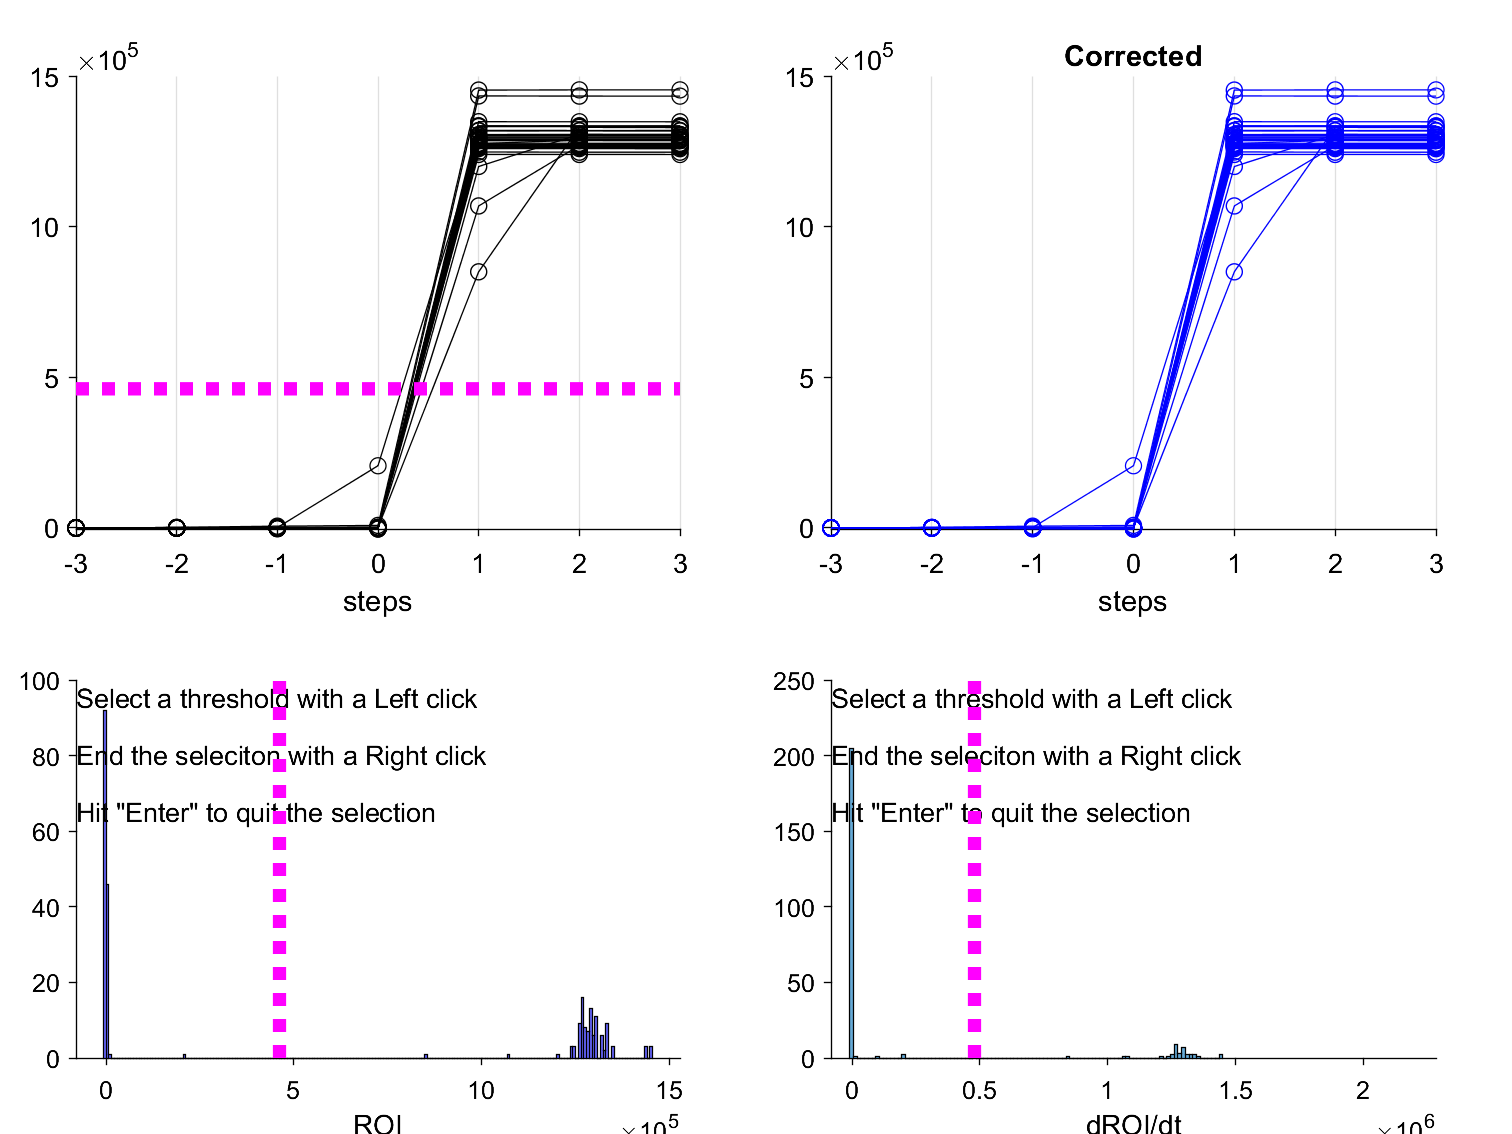

#############################
########## Please wait #########
#############################
Elapsed time is 0.153212 seconds.


FrameData = {
 'FrameInfoSideView_20210823-16-00-02.mat'  'FrameInfoTopView_20210823-16-00-04.mat'  
 'FrameInfoSideView_20210823-16-20-31.mat'  'FrameInfoTopView_20210823-16-20-34.mat'
};

nseg = size(FrameData, 1);
tLEDon = cell(1, nseg);

for i =1:nseg
    % load side view frame info
    side_info           =       load(FrameData{i, 1});
    top_info            =       load(FrameData{i, 2});
    % map LED to trigger time (blackrock), use orignal frame time for
    % better tracking across side and top videos 
    tFrames_side        =       side_info.FrameInfo.tframeOrg;
    tLEDon{i}           =       FindLEDonAuto(tFrames_side, side_info.FrameInfo.ROI, ['_Seg_' extractBefore(FrameData{i, 1}, '.mat')]); % in ms
    close(gcf)
    Indout              =       findseqmatchrev(TriggerTime*1000, tLEDon{i}, 0, 1);
    close(gcf)
    % these LEDon times are the ones that cannot be matched to trigger. It must be a false positive signal that was picked up by mistake in "tLEDon = FindLEDon(tsROI, SummedROI);"
    ind_badROI = find(isnan(Indout));
    tLEDon{i}(ind_badROI) = []; % remove them
    Indout(ind_badROI) = []; % at this point, each LEDon time can be mapped to a trigger time in b (Indout)

    % add information to FrameInfo (side)
    side_info.FrameInfo.tLEDon_ms = tLEDon{i};
    side_info.FrameInfo.Indout = Indout;
    side_info.FrameInfo.TriggerTimeEphys_ms = TriggerTime*1000;
    side_info.FrameInfo.tFramesMapped2Ephys_ms = MapVidFrameTimeToAnotherDomain(tLEDon{i},  TriggerTime(Indout)*1000, tFrames_side);

    % add information to FrameInfo (top)
    tFrames_top                                =       top_info.FrameInfo.tframeOrg;
    top_info.FrameInfo.tLEDon_ms               =       tLEDon{i};
    top_info.FrameInfo.tFramesMapped2Ephys_ms  =       MapVidFrameTimeToAnotherDomain(tLEDon{i},  TriggerTime(Indout)*1000, tFrames_top);

    %% Empirically, some events are still not well aligned. In particually, in a small subset of trials, LED starts to light up at trigger time we need to revise these trials.
    % some tLEDon need to be revised.
    imhappy = 0;
    while ~imhappy
        tLEDon_         =       CorrectLEDtimeEphysTriggerTime(side_info.FrameInfo);
        if sum(abs(tLEDon{i}-tLEDon{i}-tLEDon_))==0
            imhappy = 1;
        else
            Indout              =       findseqmatchrev(TriggerTime*1000, tLEDon_, 0, 1);
            close(gcf)
            % these LEDon times are the ones that cannot be matched to trigger. It must be a false positive signal that was picked up by mistake in "tLEDon = FindLEDon(tsROI, SummedROI);"
            ind_badROI = find(isnan(Indout));
            tLEDon{i}(ind_badROI) = []; % remove them
            Indout(ind_badROI) = []; % at this point, each LEDon time can be mapped to a trigger time in b (Indout)

            % add information to FrameInfo (side)
            side_info.FrameInfo.tLEDon_ms = tLEDon_;
            side_info.FrameInfo.Indout = Indout;
            side_info.FrameInfo.tFramesMapped2Ephys_ms = MapVidFrameTimeToAnotherDomain(tLEDon_,  TriggerTime(Indout)*1000, tFrames_side);

            % add information to FrameInfo (top)
            tFrames_top                                =       top_info.FrameInfo.tframeOrg;
            top_info.FrameInfo.tLEDon_ms               =       tLEDon{i};
            top_info.FrameInfo.tFramesMapped2Ephys_ms  =       MapVidFrameTimeToAnotherDomain(tLEDon{i},  TriggerTime(Indout)*1000, tFrames_top);
            imhappy = 1;
        end
    end

    % save side view frame
    FrameInfo = side_info.FrameInfo;
    save(['Aligned_' FrameData{i, 1}], 'FrameInfo');
    FrameInfo = top_info.FrameInfo;
    save(['Aligned_' FrameData{i, 2}], 'FrameInfo');
end

## Step 3 | Make videos based on critical time

### Example 1 | Extract all frames corresponding to the moments when animal released the lever

function names = ProduceNames(filenames, attachments);
    names = cell(1, length(filenames));
    for i =1:length(filenames)
        vidfile = extractBefore(filenames{i}, '.000.seq');
        names{i} = [attachments{i} '_' vidfile];
    end
end
